clear
addpath('..\utilities');
nodepos = load('input\Np.mat').Np;
shearrates = load('input\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('input\Tnode.mat').Tnode;
fillstatus = load('input\Fillstatus.mat').Fillstatus;
connectednodes = load('input\connectedNodes.mat').connectedNodes;
connectedelements = load('input\connectedElements.mat').connectedElements;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = meshrefiner.calcElementDiffs(elementshearrates);
tempdiffs = meshrefiner.calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);

% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates = zeros(size(elementnodeids, 1), 3);
for i = 1:size(elementnodeids, 1)
    columnids = elementnodeids(i, :);
    x = mean(nodepos(columnids, 1));
    y = mean(nodepos(columnids, 2));
    z = mean(nodepos(columnids, 3));
    elementcoordinates(i, :) = [x, y, z];
end
%elementcoordinates

[highsheardiffs, normalsheardiffs, highsheardiffsbytimestep] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 3);
tic
[newnodepos, newelementnodeids, affectedelements] = meshrefiner.createNewMeshMultiNode(nodepos, elementnodeids, highsheardiffs);
toc

Elapsed time is 8.871030 seconds.


tic
udmwriter.createUDM(newnodepos, newelementnodeids, "outputs\u_strukt_suritett.udm");
toc

Elapsed time is 13.947922 seconds.


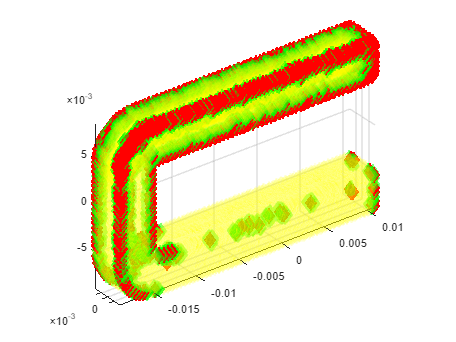

affectedelements_disp = affectedelements(find(~ismember(affectedelements, highsheardiffs(:, 1))));
unchangedelements_disp = normalsheardiffs(find(~ismember(normalsheardiffs, affectedelements)));
 
x = elementcoordinates(:, 1);
y = elementcoordinates(:, 2);
z = elementcoordinates(:, 3);

scatter3(x(highsheardiffs(:, 1)), y(highsheardiffs(:, 1)), z(highsheardiffs(:, 1)), 100, "filled", "d", "red")
hold on
scatter3(x(affectedelements_disp), y(affectedelements_disp), z(affectedelements_disp), 100, 'filled', 'd', 'green', 'MarkerFaceAlpha', 0.5,'MarkerEdgeAlpha', 0.8)
scatter3(x(unchangedelements_disp), y(unchangedelements_disp), z(unchangedelements_disp), 100,  "filled", "d","y", 'MarkerFaceAlpha', 0.1,'MarkerEdgeAlpha', 0.2)
axis equal
hold off


% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates_new = zeros(size(elementnodeids, 1), 3);
for i = 1:size(newelementnodeids, 1)
    columnids = newelementnodeids(i, :);
    x = mean(newnodepos(columnids, 1));
    y = mean(newnodepos(columnids, 2));
    z = mean(newnodepos(columnids, 3));
    elementcoordinates_new(i, :) = [x, y, z];
end

newelements =      3     2     1     4
     5     2     1     6
     1     3     7     8
     3     2     6     1
     9     3     6     1
     4     7     1     3
     5     2    10     1
    11     4     7     1
     9     3     1     8
     5     6     1     9
